% --- Rocket & Actuator Parameters ---
F_thrust = 2.386e4;
L_moment_arm = 4;
I_inertia = 1.872e04;

s = tf('s');


Pitch rate plant

G_pitchrate = (F_thrust * L_moment_arm / I_inertia) / s


G_pitchrate =
 
  5.098
  -----
    s
 
Continuous-time transfer function.
Model Properties


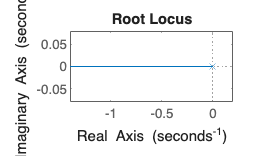

rlocus(G_pitchrate);

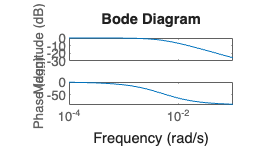


a = F_thrust*L_moment_arm/I_inertia;
s = tf('s');

omegaBW_des = 19;            % rad/s
%% K = omegaBW_des / a;
K = 0.001;
T_pitchrate = feedback(K*G_pitchrate,1);

% Now:
bode(T_pitchrate);

[GM,PM,Wcg,Wcp] = margin(T_pitchrate);
BW = bandwidth(T_pitchrate);


Pitch rate plant + actuator

% actuator (example second-order):
G_pitchrate


G_pitchrate =
 
  5.098
  -----
    s
 
Continuous-time transfer function.
Model Properties


wn = 27;   zeta = 0.7

zeta = 0.7000

Gact = wn^2 / (s^2 + 2*zeta*wn*s + wn^2)


Gact =
 
         729
  ------------------
  s^2 + 37.8 s + 729
 
Continuous-time transfer function.
Model Properties




% open-loop:
L = Gact * G_pitchrate


L =
 
           3717
  ----------------------
  s^3 + 37.8 s^2 + 729 s
 
Continuous-time transfer function.
Model Properties


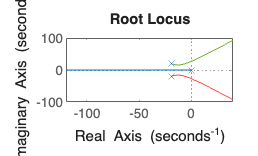

rlocus(L)


T_pitchrate_actuator = feedback(K*Gact*G_pitchrate, 1)


T_pitchrate_actuator =
 
              3.717
  ------------------------------
  s^3 + 37.8 s^2 + 729 s + 3.717
 
Continuous-time transfer function.
Model Properties


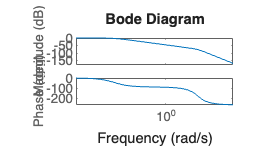

bode(T_pitchrate_actuator)

[GM,PM,Wcg,Wcp] = margin(T_pitchrate_actuator)

GM = 7.4133e+03

PM = -180

Wcg = 27.0000

Wcp = 0

BW = bandwidth(T_pitchrate_actuator)

BW = 0.0051